# Numerical Approximation of Integrals

[⇦ Overview](matlab: OpenOverview)

Integration calculates accumulation which might be area, power, a step towards averaging, or many other things. However, the challenge in many real-world problems is that the function describing the accumulation might be impossible to integrate analytically, like the Gaussian $f(x) = e^{-x^2}$, or might be unknown and sampled as data. Numerical methods for integration allow you to still approximate values of a definite integral in either case. When choosing a numerical integration method, you must balance the available information, computing resources, and error tolerance.

 This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

## What is a numerical method for integration?

### Euler's Method

The simplest method of approximating an integral is to start at a known value $(x_0,y_0)$ and attempt to follow a function $y(x)$ that is changing at a known rate (slope) $\frac{dy}{dx}=f(x)$. Let's move with constant step size $\Delta x = h$. This information allows us to create a piecewise-linear function:

$y_{\text{approx}} = \begin{cases} y_0 + f(x_0)(x-x_0) & x_0 \leq x < x_0+h = x_1 \\ y_1 + f(x_1)(x-x_1) & x_1 \leq x < x_1+h = x_2\\ \vdots \\ y_n+f(x_n)(x-x_n) & x_n \leq x < x_n+h = x_{n+1} \end{cases}$,

where $y_n = y_{\text{approx}}(x_n)$.

It is more common to organize this into a table:


$$\matrix{k & x_k = x_{k-1}+h  & \;\;\;f(x_k) & \;\;y_{k+1} = y_k+f(x_k)h}$$



$$\pmatrix{ 0 & x_0 & f(x_0) & y_0+f(x_0)h \cr 1 & x_0+h & f(x_0+h) & y_1 + f(x_0+h)h \cr 2 & \;\;\;x_0+2h\;\;\; & f(x_0+2h) & y_2 + f(x_0+2h)h \cr \vdots & \vdots & \vdots & \vdots \cr n & x_0 + nh & f(x_0+nh) & y_n + f(x_0+nh)h}$$


### Visualizing Euler's Method

syms f(x)
% Define a function such that dy/dx = f(x);
f(x) = x^3-2*x^2+1;
% Choose the left (x=a) and right (x=b) endpoints of the interval
a =  2; 
b =  30;  
% Define the value y(a) = ya
ya =  1;
% How many intervals do you want?
intervals = 7;
% How much time do you want to pause between steps?
tPause = 0.5;
showEulersMethod(@(x)f(x),a,b,intervals,ya,tPause)

**Exercise 1: Implement Euler's method**

Write a function to implement Euler's method given a function handle, an initial value, a step size, and a number of steps to take.

open eulerMethod.m

% % Uncomment this section to test your eulerMethod function using this code.
% errorAtEnd = testEulerCode(@eulerMethod,@(x) 3*x^2-1,[0,1],10,0.1)

For comparison, with 

your solution should return `errorAtEnd = 0.1450` and look like:

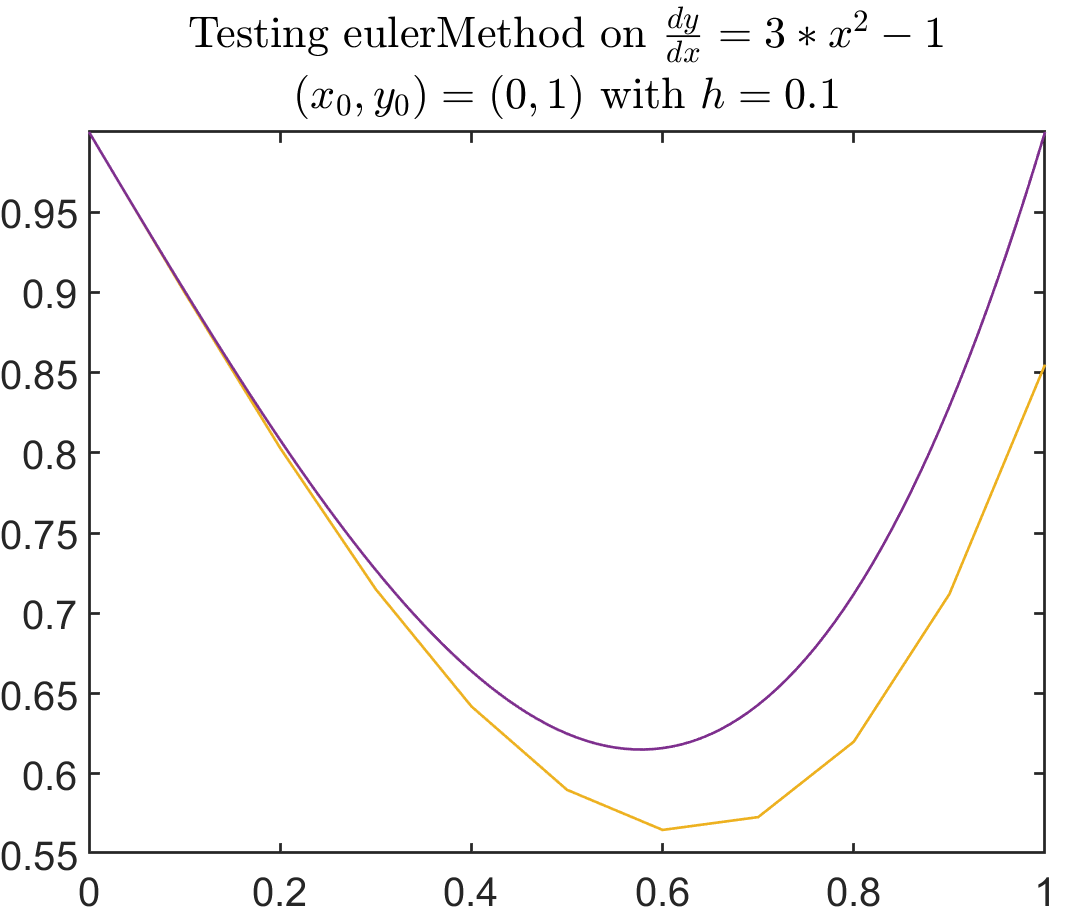

####  Try different values

- With the function $\frac{dy}{dx} = 3x^2-1$ and $(x_0,y_0)=(0,1)$, can you find a value for `h` that has an error of less than 0.01 from the true solution at $x=1$?

- What happens if you try different functions such as $\frac{dy}{dx} = \sin(x)$ or $\frac{dy}{dx} = e^x$ or $\frac{dy}{dx} = \frac{1}{x^2+1}$?

- How does your approximation change if you change the initial condition? What if you only change the $y_0$ value? Or only the $x_0$ value?

## Using Taylor Series to estimate error

If we begin with a function $\frac{dy}{dx} = f(x)$ and integrate it, we have $\displaystyle y = \int f(x)\; dx$. Consider the Taylor series expansion of the function 

$y(x) = y(x_0)+y'(x_0)(x-x_0)+\frac{y''(x_0)}{2}(x-x_0)^2 + \frac{y'''(x_0)}{6}(x-x_0)^3 + \ldots$.

In this situation, $y(x_0)=y_0$ is a known value, and $y'(x_0) = f(x_0)$, while $(x-x_0) = h$. Therefore, for the Euler method, the theoretical error at each step is approximately:

$\text{Error for one step} = y(x_0+h)-y_{\text{approx}}(x_0+h) = \left(y_0 + f(x_0)h + \frac{f'(x_0)}{2}h^2 + \mathcal{O}(h^3)\right) - \left(y_0+ f(x_0)h\right) = \frac{f''(x_0)}{2}h^2$.

To reach the desired $x$ value from $x_0$ we need to take $\frac{x-x_0}{h}$ steps:


$$\text{Error at }\; x = y(x)-y_{\text{approx}}(x) \approx \left(\frac{x-x_0}{h}\right)\left( \frac{f''(x_0)}{2}h^2+ \mathcal{O}(h^3)\right)  =\left(x-x_0\right)\left(\frac{f'(x_0)}{2}\right)h + \mathcal{O}(h^2) = \mathcal{O}(h).$$


## Experiment with a known value to confirm the practical error

If we choose a simple integrable function close to the function we are numerically integrating, we can calculate some estimates of the error of our method.

### Testing Euler's Method

Build a table to check the order of the error of an Euler's method solution to an initial value problem $\frac{dy}{dx} = f(x)$ with $y(x_0)=y_0$ for different values of $h$ when estimating the value `y(xEnd)`. 

% % Uncomment the code in this section to test your implementation of
% % Euler's method
% % Set up the parameters of the problem
% f = @(x) sin(x);
% a = 0;
% b = 1;
% 
% Fexact = @(x)-cos(x);
% 
% % Set up a vector of the number of intervals to use
% n = 10.^(1:8);
% % Define a decreasing column vector of values for h
% h = double((b-a)./n)';
% 
% FEst = nan(size(h));
% for k = 1:length(n)
%     [~,yOut] = eulerMethod(f,[a Fexact(a)],n(k),h(k));
%     FEst(k) = yOut(end);
% end
% FErr = double(Fexact(b)*ones(size(FEst))-FEst);
% 
% ratio = [nan; FErr(2:end)./FErr(1:end-1)];
% estOrd = -log10(ratio);
% vals = [h FErr ratio estOrd];
% format long
% T = array2table(vals,"VariableNames",...
%     ["h", "Error", "Ratio", "Estimated Order"]);
% T(2:end,:)

### Example: 3-point Gaussian quadrature

Consider how to calculate $\displaystyle \int_{-1}^1 f(x)\; dx$ using the best approximation with various numbers of points. A first-order approximation to $f(x)$ is linear, so then the integral is a trapezoid with area: 


$$\frac{1}{2}\left(f(-1)+f(1)\right)2 = f(-1)+f(1) = m(-1)+f(0)+m(1)+f(0) = 2f(0)$$


The general form of an n-point Gaussian quadrature formula is

$\displaystyle \int_{-1}^1 f(x)\; dx \approx \sum_{i=1}^n w_if(x_i)$,

where the weights, $w_i$, and the points, $x_i$, are chosen to minimize error. The one-point formula becomes 

$\displaystyle \int_{-1}^1 f(x)\; dx \approx 2f(0)$    with $w_1 = 2$ and $x_1 = 0$. 

The 3-point Gaussian quadrature formula is


$$\int_{-1}^1 f(x)\; dx \approx \frac{5}{9}f\left(-\sqrt{\frac{3}{5}}\right) + \frac{8}{9}f(0)+\frac{5}{9}f\left(\sqrt{\frac{3}{5}}\right)$$


Implementing this, we have

f = @(x) 2*x.^5-3*x.^2;
a = -1.4;
b = 2.3;
Fexact = double(int(f(x),a,b))
Fapprox = gauss3pt(f,a,b)
Ferror = Fexact-Fapprox

####  Try different values

- Try different functions of various degrees such as $f(x) = -8x^4+2x^3-5x$ or $f(x) = 1.7x^5-3$ or $f(x) = 0.6x^7-8x^2$. What do you observe about the error of this method?

- Try different functions that are not polynomials such as $f(x) = \sin(x/4)$ or $f(x) = e^{x}$. What do you observe about the error of this method?

- Try different values for $a$ and $b$, the endpoints of the integral. What do you observe about the error of this method? 

**Exercise 2: Implement 2-point Gaussian quadrature**

The weights for a 2-point Gaussian quadrature approximation are $w_1 = w_2 = 1$ while the points to evaluate at are $x_1 = -\frac{1}{\sqrt{3}}$ and $x_2 = \frac{1}{\sqrt{3}}$. Use `gauss3pt` as a template for creating your function.

open gauss2pt.m

**Check Exercise 2: Implementing 2 point Gaussian quadrature**

% Run this code to test your gauss2pt function
calcError = testGauss2PtCode(@gauss2pt)

### Simpson's rule

When approximating a continuous function from discrete data using a piecewise linear interpolation is not sufficient, you may want to try approximating your function using piecewise polynomials of higher orders. This was the approach taken by Thomas Simpson and Johannes Kepler. [1,2]

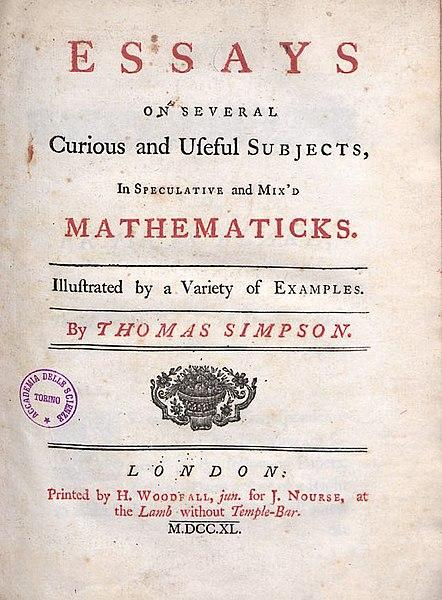                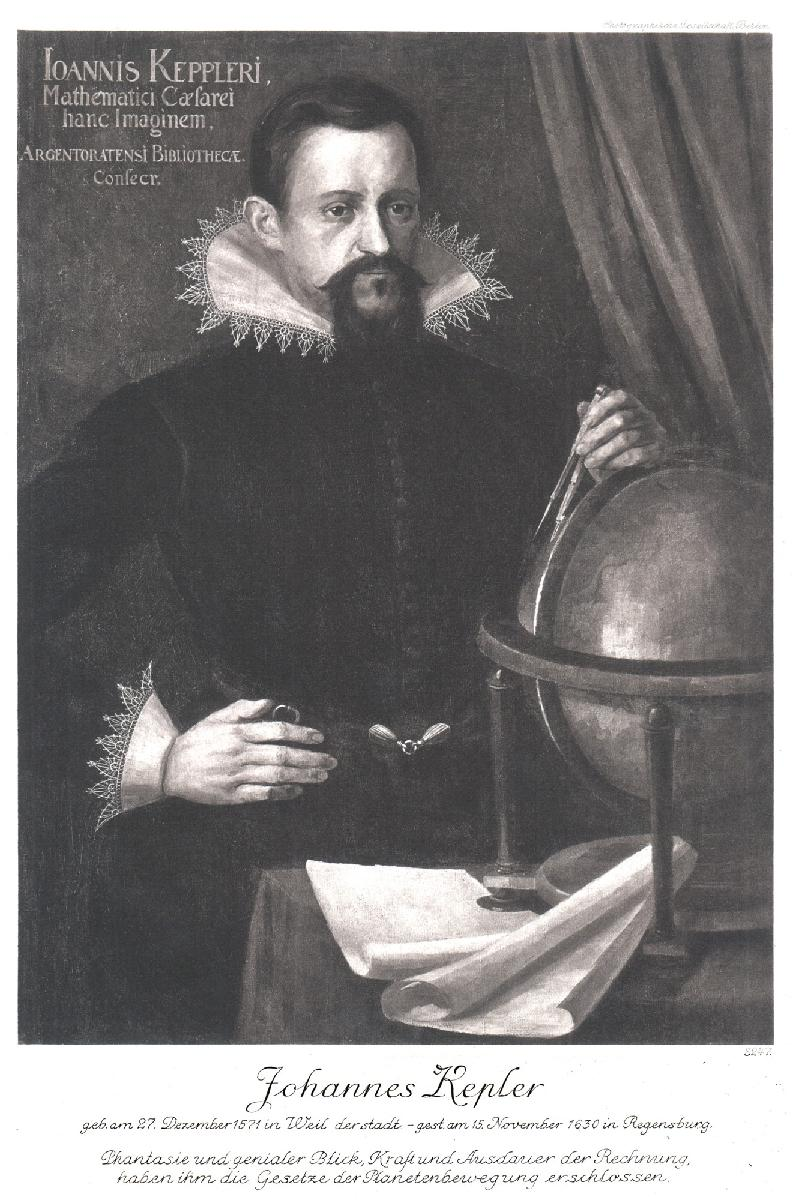

###   Visualizing Simpson's rule

syms f(x)
% Define a function such that dy/dx = f(x);
f(x) = (x^3-2*x^2+1)*sin(0.5*x);
% Choose the left (x=a) and right (x=b) endpoints of the interval
a =  2; 
b =  30;  
% Define the value y(a) = ya
ya =  1;
% How many intervals do you want?
intervals = 4;
showSimpsonsMethod(@(x)f(x),a,b,intervals)

**Exercise 3: Implement Simpson's rule**

Approximating our function $f(x)$ by a quadratic polynomial that passes through the points $x=a$, $x=b$, and $x= \frac{a+b}{2}$, we end up with the formula

$\displaystyle \int_a^b f(x)\; dx = \frac{h}{3}\left(f(a)+4f\left(\frac{a+b}{2}\right)+f(b)\right)$,  where $\displaystyle h = \frac{b-a}{2}$.    $(\mathcal{S})$

Using 

formula $(\mathcal{S})$, write a function called `simpsonsRule` that will use $n$ piecewise quadratic functions to approximate the integral $\displaystyle \int_a^b f(x)\; dx$. 

open simpsonsRule.m

  **Pro-tip**. To ensure that both `a` and `b` are endpoints of your discretized interval, you should use

rather than

since floating-point representation of `(b-a)/n` can result in `a:(b-a)/n:b `not including the value `b` in some cases.

% Use this code to check the computations of simpsonsRule

% Set up the function, endpoints, and number of subintervals
f = @(x) 3*x.^3-2;
a = 0;
b = 2;
n = 1;

% Run the simpsonsRule approximation code
simpsonsRule(f,a,b,n)
% The exact value of this integral is:
syms x
double(int(f(x),a,b))

**Checking Exercise 3: implementation of Simpson's rule**

errors = testSimpsonsRule(@simpsonsRule);

### Empirically Testing the error in Simpson's rule

Build a table to check the order of the error of an integral over finite bounds $[a,b]$ with different numbers of subintervals, $n$. Note that the length of each subinterval is $h = \frac{b-a}{n}$.

% Set up the parameters of the problem
f = @(x) exp(x).*cos(x);
a = 0;
b = 1;

% Use the symbolic engine to calculate the integral
syms x
Fexact = int(f(x),a,b);

% Set up a vector of the number of intervals to use
n = 2.^(1:8);
% Define a decreasing column vector of values for h
h = double((b-a)./n)';

FEst = nan(size(h));
for k = 1:length(n)
    FEst(k) = simpsonsRule(f,a,b,n(k));
end
FErr = double(Fexact-FEst);

ratio = [nan; FErr(2:end)./FErr(1:end-1)];
estOrd = -log2(ratio);
vals = [h FErr ratio estOrd];
format long
T = array2table(vals(2:end,:),"VariableNames",...
    ["h", "Error", "Ratio", "Estimated Order"])

####  **Reflect: Expected Error for Simpson's Rule**

- Given the estimated order you calculated with $f(x) = e^x\cos(x)$ and the connection of the order of error to the Taylor series, which calculations can be computed exactly using Simpson's rule with $n=1$. Why or why not?

a) $\displaystyle \int_0^4 \sin(x)\; dx$                            

b) $\displaystyle \int_0^1 x^2-\frac{1}{6}x+3\; dx$                    

c) $\displaystyle \int_{-7}^{13} 0.53x^3+1.7x^2-8x+2\; dx$

d) $\displaystyle \int_{-1}^{1} x\; dx$                                    

          2. When the error is 0, what is the optimal step size to choose?

## What happens if the step size is constrained?

In all of the examples of numerical methods so far, except for `ode23s`, we have assumed that the step size is identical throughout the solution. This is not a reasonable assumption. How can you modify the solvers you have created to work with arbitrary step sizes? 

### Modifying Euler's method

Euler's method is quite simple to update. While the basic formula was

$\displaystyle \int_a^b f(x)\; dx \approx \sum_{k=1}^n f(x_k)\left(\frac{b-a}{n}\right)$,      with $\displaystyle x_k = a+(k-1)\left(\frac{b-a}{n}\right)$,

if the $k^{\text{th}}$ interval is $\displaystyle [x_k,x_{k+1}]$, with $x_1 = a$ and $x_{n+1} = b$, then 


$$\displaystyle \int_a^b f(x)\; dx = \sum_{k=1}^n f(x_k)\left(x_{k+1}-x_k\right).$$


### Modifying Simpson's rule

Simpson's rule takes a bit more effort to update because we need to think carefully about what it means to fit a quadratic through the points that we know. There will be different cases for Simpson's rule depending on whether we have an even or odd number of sub-intervals. 

#### Even number of sub-intervals

If we have an even number of subintervals, $S$, and thus the $k^{\text{th}}$ subinterval is $[x_k,x_{k+1}]$, we can compute a Simpson's rule calculation with $\displaystyle n = \frac{S}{2}$ and $h_{m} = x_{m+1}-x_m$:

$\displaystyle \int_a^b f(x)\; dx \approx \sum_{k=1}^n \frac{x_{2k+1}-x_{2k-1}}{6}\left[\left(2-\frac{h_{2k}}{h_{2k-1}}\right)f(x_{2k-1}) + \left(\frac{(x_{2k+1}-x_{2k-1})^2}{h_{2k}h_{2k-1}}\right)f(x_{2k}) + \left(2-\frac{h_{2k-1}}{h_{2k}}\right)f(x_{2k+1})\right]$.

#### Odd number of sub-intervals

If we have an odd number of subintervals, we cannot pair them all up to create appropriate quadratic curves through each triplet. One way to address this case is to drop the final subinterval to reduce ourselves to the even subintervals case and then use the last two subintervals to create an approximate quadratic to use in the numerical integration of the final subinterval.

### Cannot update Gaussian quadrature

Gaussian quadrature relies on knowing values at particular points. Gaussian quadrature cannot be used if those integrand values are not known.

### Application of interpolation

One method that can be used to regularize irregular data for use in standard numerical methods is to interpolate the necessary values at the desired evenly-spaced points. 

## References

[1] Thomas Simpson, [Simpson, Thomas – Essays on several curious and useful subjects, in speculative and mix'd mathematicks, 1740 – BEIC 768468](https://commons.wikimedia.org/wiki/File:Simpson,_Thomas_%E2%80%93_Essays_on_several_curious_and_useful_subjects,_in_speculative_and_mix'd_mathematicks,_1740_%E2%80%93_BEIC_768468.jpg), marked as public domain, more details on [Wikimedia Commons](https://commons.wikimedia.org/wiki/Template:PD-old) Accessed Apr 14, 2022.

[2] Portrait of Johannes Kepler. Photogravure by Photographische Gesellschaft, Berlin (Photographic company), published by Photographische Gesellschaft, Berlin (Photographic company). [https://library.si.edu/image-gallery/72833](https://library.si.edu/image-gallery/72833) Accessed Apr 14. 2022.

[⇦ Overview](matlab: OpenOverview)

## Test Functions

function out = testEulerCode(eulerMethod,f,init,n,h)  
% TESTEULERCODE runs the function EULERMETHOD with inputs F, INIT, N, and H
% and compares the results to the expected values
% EULERMETHOD and F are function handles,
% INIT is a vector of initial conditions,
% N is the number of steps to take and
% H is the size of each step
syms x
F(x) = int(f(x),x);
F(x) = F(x) + init(2)-F(init(1));
[xVals,yVals] = eulerMethod(f,init,n,h);
plot(xVals,yVals);
fStr = func2str(f);
idx = regexp(fStr,'[)]')+1;
title("Testing eulerMethod on $\frac{dy}{dx} = "+fStr(idx:end)+"$","Interpreter","latex")
subtitle("$(x_0,y_0) = ("+init(1)+","+init(2)+")$ with $h="+h +"$","Interpreter","latex")
hold on
x0 = init(1);
plot(x0:.1*h:x0+n*h,double(F(x0:.1*h:x0+n*h)))
hold off
out = double(F(x0+n*h)-yVals(end));
end

function F = gauss3pt(f,a,b)
% GAUSS3PT implements a three point Gaussian quadrature approximation
% of the integral from A to B of the function defined by function handle F

% Set up the parameters
x1 = -sqrt(3/5);
x2 = 0;
x3 = sqrt(3/5);
w1 = 5/9;
w2 = 8/9;
w3 = 5/9;

% Change coordinates from [-1,1] to [a,b]
xShifted = (b-a)/2*[x1; x2; x3]+(b+a)/2;
wScaled = (b-a)/2*[w1 w2 w3];

% Use matrix multiplication to compute the weighted sum
F = wScaled*f(xShifted);
end

function [errors,out] = testGauss2PtCode(gauss2pt)
% TESTGAUSS2SPCODE runs several known functions through
% GAUSS2PT(f,a,b) and compares to the expected values
%
% ERRORS collects the errors for each test
% OUT is a boolean tracking success or failure of all tests
syms x
errors = nan([1,3]);

% Test 1
try
    disp("Running test 1...")
    tol = 1e-15;
    f = @(x) 3*x.^2-1;
    Fexpected = double(int(f(x),-1,1));
    Fapprox = gauss2pt(f,-1,1);
    errors(1) = Fexpected - Fapprox;
    assert(abs(Fexpected-Fapprox)<tol,"Failed quadratic test with standard bounds.")

    % Test 2
    disp("Running test 2...")
    tol = 1e-14;
    f = @(x)1.6*x.^3-4*x.^2-5;
    Fexpected = double(int(f(x),-2,1.6));
    Fapprox = gauss2pt(f,-2,1.6);
    errors(2) = Fexpected - Fapprox;
    assert(abs(Fexpected-Fapprox)<tol,"Failed cubic test with scaled bounds.")

    % Test 3
    disp("Running test 3...")
    tol = 1e-14;
    f = @(x) x.^5-9*x+2;
    Fexpected = 9.168767999999996;
    Fapprox = gauss2pt(f,-2,1.6);
    errors(3) = double(int(f(x),-2,1.6)) - Fapprox;
    assert(abs(Fexpected-Fapprox)<tol,"Failed quintic test with scaled bounds.")

    out = 1;
    disp("All tests passed.")
catch
    out = 0;
    disp("Please update your gauss2pt code and try again.")
end

end

function [errors,out] = testSimpsonsRule(simpsonsRule)
% TESTSIMPSONSRULE runs several known functions through
% SIMPSONSRULE(f,a,b,n) and compares to the expected values
%
% ERRORS collects the errors for each test
% OUT is a boolean tracking success or failure of all tests
syms x
errors = nan([1,4]);

% Test 1
try
    disp("Running test 1...")
    tol = 1e-16;
    f = @(x) 3*x.^2-1;
    Fexpected = double(int(f(x),-3,1));
    Fapprox = simpsonsRule(f,-3,1,1);
    errors(1) = Fexpected - Fapprox;
    assert(abs(Fexpected-Fapprox)<tol,"Failed quadratic test with one interval.")

    % Test 2
    disp("Running test 2...")
    tol = 1e-16;
    f = @(x)1.6*x.^3-4*x.^2-5;
    Fexpected = double(int(f(x),-2,1.6));
    Fapprox = simpsonsRule(f,-2,1.6,4);
    errors(2) = Fexpected - Fapprox;
    assert(abs(Fexpected-Fapprox)<tol,"Failed cubic test with four subintervals.")

    % Test 3
    disp("Running test 3...")
    tol = 1e-15;
    f = @(x) x.^5-9*x+2;
    Fexact = double(int(f(x),0,4));
    Fexpected = 618.6724950481525;
    Fapprox = simpsonsRule(f,0,4,11);

    errors(3) = Fexact - Fapprox;

    assert(abs(Fexpected-Fapprox)<tol,"Failed quintic test with 11 subintervals")

    % Test 4
    disp("Running test 4...")
    n = randi([80,200],1);
    Fapprox2 = simpsonsRule(f,0,4,n);
    errors(4) = Fexact - Fapprox2;
    assert(abs(errors(4))<abs(errors(3)),"Failed: for a quintic equation, increasing the number of subintervals" + ...
        " should decrease the error.")

    out = 1;
    disp("All tests passed.")
catch
    out = 0;
    disp("Please update your simpsonsRule code and try again.")
end

end

function showEulersMethod(f,a,b,n,F0,tPause)
% SHOWEULERSMETHOD plots an Euler's Method approximation to the solution to
% the initial value problem dy/dt = f(t) from t=a to t=b with y(a) = F0,
% step size (b-a)/n and a pause of length tPause between each graphed step
% f is a function handle
% a, b, F0 and tPause are doubles, while n is an integer expressed as a double

% Clear the figure, if one exists
clf

% Create the values needed for this plot
syms t
F(t) = int(f(t),t);
Freal = @(t) F(t)-F(a)+F0;
tVals = linspace(a,b,101);
FVals = double(Freal(tVals));
tDisc = linspace(a,b,n+1);
fVals = double(f(tDisc));
FEuler = zeros(size(tDisc));
FEuler(1) = F0;
FEuler(2) = FEuler(1)+fVals(1)*(tDisc(2)-tDisc(1));

% Plot the solution curve
plot(tVals,FVals,"SeriesIndex",1,"LineWidth",2);

% Set the x and y limits so they don't change as new values are added
% Include a 5% buffer on the y limits to allow for some error to be visible
ax = gca;
xlim(ax.XLim);
yScaleShift = (ax.YLim(2)-ax.YLim(1))*0.05;
ylim([ax.YLim(1)-yScaleShift ax.YLim(2)+yScaleShift]);

% Select an appropriate number of points to use for the vector field mesh
% so the solution will clearly have the appropriate slope at each point
if n <= 20 && n >= 10
    tSteps = (b-a)/n;
elseif n < 10
    tSteps = (b-a)/((ceil(10/n)+1)*n);
elseif n > 20
    tSteps = (floor(n/10))*(b-a)/n;
end

hold on

% Create the vector field background
yDisc = linspace(ax.YLim(1),ax.YLim(2),11);
[tMesh,yMesh] = meshgrid(a:tSteps:b,yDisc);
quiver(tMesh,yMesh,tSteps*ones(size(tMesh)),tSteps*f(tMesh).*ones(size(tMesh)),"SeriesIndex",2,"ShowArrowHead","off")

% Create the graphics objects to use for the animation of the Euler's
% method approximation
pDot = plot(a,F0,"o","SeriesIndex",3,"MarkerFaceColor","auto");
q = quiver(tDisc(1),FEuler(1),tDisc(2)-tDisc(1),fVals(1)*(tDisc(2)-tDisc(1)),"SeriesIndex",2);
q.ShowArrowHead = "off";
pLine = plot(tDisc(1:2),[FEuler(1) FEuler(2)],"SeriesIndex",3,"LineWidth",2);

hold off

% Label the plot
title("Visualizing Euler's Method")
xlabel("x")
ylabel("y")
legend(["Solution" "Slope field" "" "" "Euler's method"],"Location","best")

% Animate the plotting of the Euler's method approximation
for k = 2:n
    pDot.XData = tDisc(k);
    pDot.YData = FEuler(k);
    q.XData = tDisc(k);
    q.YData = FEuler(k);
    % Scale the tangent vector by 10 for better visibility
    q.UData = 10*(tDisc(k+1)-tDisc(k));
    q.VData = 10*(fVals(k)*(tDisc(k+1)-tDisc(k)));
    drawnow
    pause(tPause)
    FEuler(k+1) = FEuler(k)+fVals(k)*(tDisc(k+1)-tDisc(k));
    pLine.XData = tDisc(1:k+1);
    pLine.YData = FEuler(1:k+1);
end

% Show the entire Euler's method approximation with all points
pDot.XData = tDisc;
pDot.YData = FEuler;
end

function showSimpsonsMethod(f,a,b,n)
% SHOWSIMPSONSMETHOD plots the function y=f(x) over the interval from x=a
% to x=b and compares that to the positive and negative signed areas for a
% Simpson's rule approximation of the integral of f(x) from a to b using n
% intervals

% Clear any figure that exists
clf

% Set up the values to be used in Simpson's rule
xVals = linspace(a,b,2*n+1);
yVals = double(f(xVals));

% Iterate over each interval and draw the signed regions under the
% quadratic approximation
hold on
for k = 1:n
    drawSignedRegion(xVals(2*k-1:2*k+1),yVals(2*k-1:2*k+1),["b" "y"])
end

% Calculation the values and plot the function y = f(x)
xAll = linspace(a,b,301);
yAll = double(f(xAll));
plot(xAll,yAll,"LineWidth",2,"SeriesIndex",1)
hold off

% Annotate the plot
title("Visualize Simpson's rule")
subtitle("Number of intervals: " + n)
xlabel("x")
ylabel("y")
end

function drawSignedRegion(x,y,col)
% DRAWSIGNEDREGION takes three points defined by the vectors x and y,
% calculates the parabola through those points, and then draws a signed
% region where positive area is denoted with color col(1) and negative area is
% denoted with color col(2)

% Define a small enough step size for a smooth curve to result
step = abs(x(end)-x(1))/200;

% Ensure that x and y are both column vectors
x = reshape(x,3,1);
y = reshape(y,3,1);

% Solve for the quadratic through the points x,y
XMat = [x.^2 x ones([3,1])];
solT = XMat\y;
topLine = @(t)solT(1)*t.^2+solT(2)*t+solT(3);

% Calculate the values defining the colored regions
xVals = linspace(x(1),x(end),ceil((abs(x(end)-x(1))/step)));
topVals = topLine(xVals);
botLine = zeros(size(xVals));

% Determine the appropriate color for each region and fill it in
colIdx = topVals<0;
if any(colIdx) && any(~colIdx)
    if colIdx(1)
        startIdx = find(~colIdx,1);
        endIdx = find(~colIdx,1,"last");
        fill([xVals fliplr(xVals)],[topVals botLine],col(2))
        fill([xVals(startIdx:endIdx) fliplr(xVals(startIdx:endIdx))],[topVals(startIdx:endIdx) botLine(startIdx:endIdx)],col(1))
    else
        startIdx = find(colIdx,1);
        endIdx = find(colIdx,1,"last");
        fill([xVals fliplr(xVals)],[topLine(xVals) botLine],col(1))
        fill([xVals(startIdx:endIdx) fliplr(xVals(startIdx:endIdx))],[topVals(startIdx:endIdx) botLine(startIdx:endIdx)],col(2))
    end
elseif all(colIdx)
    fill([xVals fliplr(xVals)],[topVals botLine],col(2))
else
    fill([xVals fliplr(xVals)],[topVals botLine],col(1))
end
end

% Suppress code warnings that do not apply in this case
%#ok<*DEFNU>